Companion software for "Volker Ziemann, *Hands-on Accelerator physics using MATLAB, CRCPress, 2019*" ([https://www.crcpress.com/9781138589940](https://www.crcpress.com/9781138589940))

# Large-amplitude oscillations in longitudinal phase space (Section 5.4)

Volker Ziemann, 211108, CC-BY-SA-4.0

The dynamics of particles in the longitudinal phase-space is goverend by the equations of a mathematical pendulum, which can be integrated in closed form with the help of Jacobi elliptic functions. This allows us to map initial phase-space coordinates to those at any later time without iterating over all intermediate times. The algorithm is described in Section 5.4 in the book. Here we use the function pendulum_tracker() from the appendix below to implement this calculation. The top-level code randomly places a number of particles` N` in a square, shown in green, and the plots the final coordinates in black. All parameters can be changed to explore the parameter space.

clear all; close all
N=100;            % number of particles
Omegas=0.25;      % synchrotron frequency
Ts=2*pi/Omegas;   % the time for one small-amplitude oscillation

In the following line we adjust the duration of the simulation, either by hand or using the slider in the commented-out line. I suggest to slowly increase the time in steps of `0.2*Ts` and eventually look at` dt=Ts*1000`.

dt=Ts*0.2;                          % integration time=duration
%dt=Ts*0.4     % adjust duration

Next we define the initial particle distribution, which is then shown as the green cloud of dots, draw the separatrix, annotate the axes, and write the duration of the simulation into the plot.

x0=[0.0,0.4];     % center of initial (green) distribution
dx=[0.3,0.1];     % spread of initial (green) distribution

It is fun to play with these parameters, maybe place the initial coordinates right on the separatrix with `x0=[0,0.5]`, or make the distribution very wide by choosing `dx=[2*pi,0.1].` 

phi=-pi:0.01:pi;  % range of angles
separatrix=2*Omegas*cos(0.5*phi);     % plot the separatrix
hold off; plot(phi,separatrix,'k',phi,-separatrix,'k')
axis([-pi,pi,-0.67,0.67]); hold on; pause(0.001)
set(gca,'xtick',[-pi,-pi/2,0,pi/2,pi],'fontsize',14, ...
  'xticklabels',{'-\pi','-\pi/2','0','\pi/2','\pi'})             % xlabels
text(-2.8,-0.57,['After ',num2str(dt/Ts),' T_s'],'fontsize',16)  % duration

Now we are ready to loop over all` N` particles. Inside the loop, we first generate the initial particle coordinates `x0` where we plot a green dot. Then we map the coordinates `x1` to those after the time duration dt, where we plot a black dot. After a short pause to allow MATLAB to update the plotm we continue with the next particle.

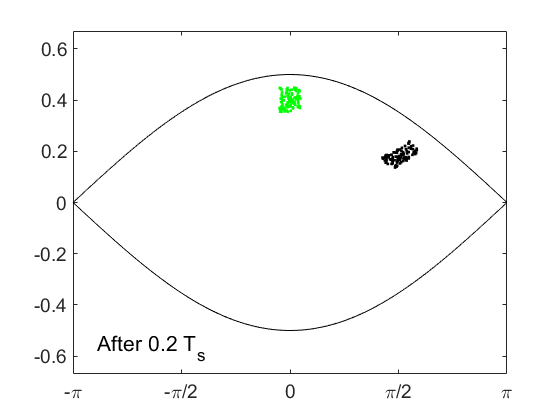

for k=1:N   % loop over particles
  x=x0+(rand(1,2)-0.5).*dx;  
  plot(x(1),x(2),'g.');
  x1=pendulumtracker(x,Omegas,dt); 
  plot(x1(1),x1(2),'k.');
  pause(0.001)
end

And now it's time to explore the phase space of the mathematical pendulum further. Have fun!

## Appendix

The function` pendulumtracker()` receives the phase-space coordinates `x` at the start, the small-amplitude synchrotron frequency `omega`, and the integration time `dt` as input and returns the phase-space coordinates `xout`. Internally, it integrates the equations of motion for a mathematical pendulum in closed form using Jacobi elliptic functions. This is much faster than numerically integration, expecially for extremely large times, such as thousands or even millions of synchrotron periods. The coding closely follows Section 5.4, especially Equations 5.50 to 5.54.

function xout=pendulumtracker(x,omega,dt)
k2=(0.5*x(2)/omega)^2+sin(0.5*x(1))^2;      % just after eq. 5.45
k=sqrt(k2);
if (x(1)>pi) x(1)=x(1)-2*pi; end            % map back into range [-pi,pi]
if (x(1)<-pi) x(1)=x(1)+2*pi; end           
s=1; if (x(1)<0) s=-s; x(1)=-x(1); end      % keep track of quadrant
s1=1; if (x(2)<0) s1=-s1; end
if (k>1)   % outside the separatrix
  % kelf=ellipticK(1/k2);
  kelf=ellipke(1/k2);                                % faster
  trev=2*kelf/(k*omega);
  t0=mod(dt,trev);
  tmp=s1*k*omega*t0+s*ellipticF(0.5*x(1),1/k2);
  % tmp=s1*k*omega*t0+s*elliptic12(0.5*x(1),1/k2);     % faster
  [sn,cn,dn]=ellipj(tmp,1/k2);    
  if (abs(tmp) > kelf) sn=-sn; end
  xout(1)=2*asin(sn);                % eq. 5.52
  xout(2)=2*s1*omega*k*dn;
else       % inside the separatrix
  % trev=4*ellipticK(k2)/omega;
  trev=4*ellipke(k2)/omega;                          % faster
  t0=mod(dt,trev);
  z0=asin(min(1,sin(0.5*x(1))/k));
  tmp=s1*omega*t0+s*ellipticF(z0,k2);
  % tmp=s1*omega*t0+s*elliptic12(z0,k2);               % faster
  [sn,cn,dn]=ellipj(tmp,k2);
  xout(1)=2*asin(k*sn);               % eq. 5.54
  xout(2)=2*s1*omega*k*cn;
end
end

This version uses the built-in function `ellipticF()`, which is rather slow. They should be replaced by `elliptic12()` from the package elliptic from[  ](https://github.com/moiseevigor/elliptic)[https://github.com/moiseevigor/elliptic](https://github.com/moiseevigor/elliptic) , which speeds up the simulation.